# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv');

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

size(data)

ans =    570    32


summary(data)


Variables:

    id: 570×1 double

        Values:

            Min             8670
            Median    9.0616e+05
            Max       9.1132e+08

    diagnosis: 570×1 cell array of character vectors

    radius_mean: 570×1 double

        Values:

            Min               6.981    
            Median            13.34    
            Max               28.11    
            NumMissing        1        

    texture_mean: 570×1 double

        Values:

            Min             9.71    
            Median        18.835    
            Max            39.28    

    perimeter_mean: 570×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 570×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    


%remove any identical rows from the table
data = unique(data, 'rows');

size(data)

ans =    569    32



%remove the irrelevant feature id
data (:, 'id') = [];

size(data)

ans =    569    31



%find which rows contain missing values
nans = isnan(data {:, 'radius_mean'})

nans = 569×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


%use the resuult to delete the entire row
data(nans, :) = [];

size(data)

ans =    568    31


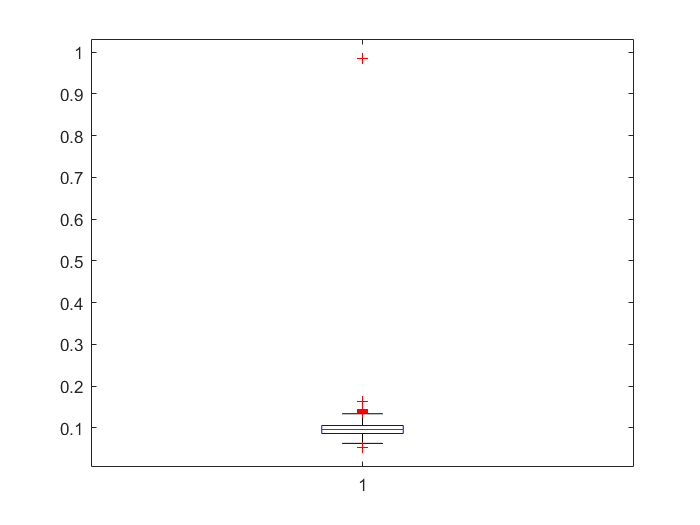


%generate a boxplot of all our smoothness_mean feature values
boxplot(data {:, 'smoothness_mean'})


%datacurser reveals the outlier is in the 149th row
%delete the associated example
data(149, :) = [];

size(data)

ans =    567    31



% how many examples for 25%:
nTest = round(0.25 * size(data,1))

nTest = 142

% re-seed Matlab's random number generator:
rng(1)
% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =    142    31


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    425    31


% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'diagnosis'});
test_examples = data_test;
test_examples(:,'diagnosis') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'diagnosis'});
train_examples = data_train;
train_examples(:,'diagnosis') = [];